
clear ; close all ; clc

c = 1;
I = 10.^[-1:2];
K = 50;
n_I = length(I);

fv = logspace(-2, 3, 1000)';
wv = 2*pi*fv;
n_fv = length(fv);
Gain = nan(n_fv, n_I);
Phase = nan(n_fv, n_I);
for n = 1:n_I
    P = tf(c, [I(n) c]);
    C = tf(K,1);
    G = P*C;
    H = minreal(G / (1 + G));
    %H.IOdelay = 0.02;
    [mag,phase,wout] = bode(H, wv);
    Gain(:,n) = squeeze(mag);
    Phase(:,n) = squeeze(phase);
end


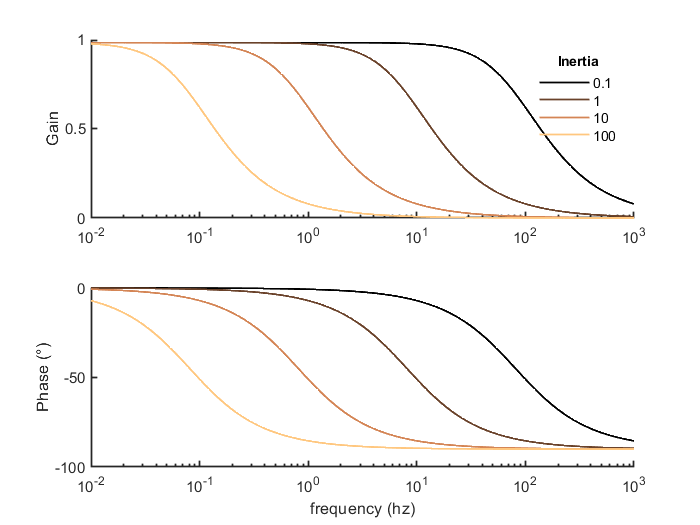

fig = figure (1);
set(fig, 'Color', 'w', 'units', 'inches')
cc = copper(n_I);

ax(1) = subplot(2,1,1) ; cla ; hold on ; ylabel('Gain')
    h.Gain = plot(fv, Gain);
    
ax(2) = subplot(2,1,2) ; cla ; hold on ; ylabel('Phase (°)')
    h.Phase = plot(fv, Phase);
    xlabel('frequency (hz)')
    
set(ax, 'Color', 'none', 'LineWidth', 1, 'XScale', 'log')
set(h.Gain, {'Color'}, num2cell(cc,2))
set(h.Phase, {'Color'}, num2cell(cc,2))
set([h.Gain , h.Phase], 'LineWidth', 1)

leg = legend(h.Gain, string(I), 'Box', 'off');
leg.Title.String = 'Inertia';

clear ; clc
syms I c s K

P = 1 / (I*s + c)

$$P = \frac{1}{c+\text{I}\,s}$$

C = K*s

$$C = K\,s$$

G = P*C

$$G = \frac{K\,s}{c+\text{I}\,s}$$

H = G / (1 + G);
H = collect(simplify(expand(H)),s)

$$H = \frac{K\,s}{\left(\text{I}+K\right)\,s+c}$$